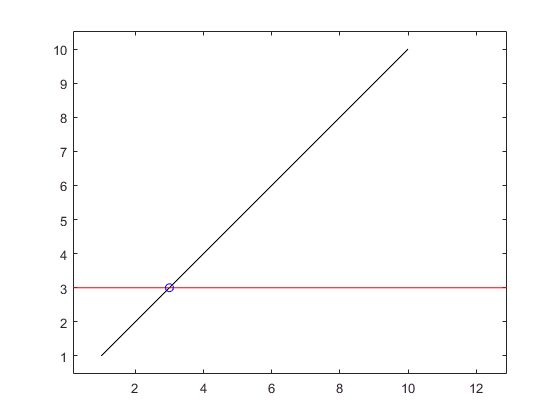

% define the x- and y-data for the original line we would like to rotate
x = 1:10;
y = 1:10;
% create a matrix of these points, which will be useful in future calculations
v = [x;y];
% choose a point which will be the center of rotation
x_center = x(3);
y_center = y(3);
% create a matrix which will be used later in calculations
center = repmat([x_center; y_center], 1, length(x));
% define a 60 degree counter-clockwise rotation matrix
theta = -pi/4;       % pi/3 radians = 60 degrees
R = [cos(theta) -sin(theta); sin(theta) cos(theta)];
% do the rotation...
s = v - center;     % shift points in the plane so that the center of rotation is at the origin
so = R*s;           % apply the rotation about the origin
vo = so + center;   % shift again so the origin goes back to the desired center of rotation
% this can be done in one line as:
% vo = R*(v - center) + center
% pick out the vectors of rotated x- and y-data
x_rotated = vo(1,:);
y_rotated = vo(2,:);
% make a plot
plot(x, y, 'k-', x_rotated, y_rotated, 'r-', x_center, y_center, 'bo');
axis equal